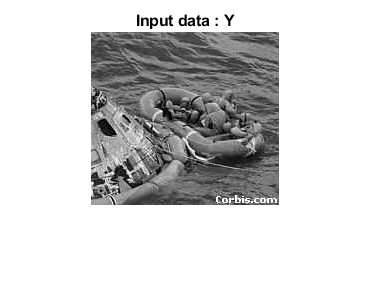

clc
clear

X = imread('X2.bmp');
Y = imread('Y2.bmp');

doubleX = double(X);
doubleY = double(Y);
doubleX = [doubleX; ones(1, size(doubleX, 2))];

[m,n] = size(doubleX);

%Grevill
M = size(doubleX, 1);

a = doubleX(1, :).';
A(1, :) = a;
if((a.' * a) == 0)
    RES = a;
else
    RES = a / (a.' * a);
end
e = 1^-6;

for k=2:M
    a = doubleX(k, :).';
    AA = RES * A;
    one = ones(1, size(AA, 1));
    Z = diag(one) - AA;
    atZa = a.' * Z * a;
    A(k, :) = a;
    if atZa > e %проверка на лінійну незалежність вектора який ми додаємо
        RES = RES - (Z * a * a.' * RES) / atZa;
        RES(:, k) = (Z * a) / atZa;
    else
        R = RES * RES.';
        atRa = a.' * R * a;
        RES = RES - (R * a * a.' *RES) / (1 + atRa);
        RES(:, k) = (R * a) / (1 + atRa);
    end
end

grevX = RES;
XX_grev = grevX' * grevX;

Z_grev = eye(M) - XX_grev;
V = zeros(size(doubleY, 1), size(grevX, 2));
A_Grev = doubleY * grevX+ V * Z_grev.';
RES_Grev = A_Grev * doubleX;

RES_Grev_uint = uint8(RES_Grev);


%Mura-Penrouse
d = 10;
X1=[];
X2=[];
eps = 0.002;
difX1X2 = 200;
while (difX1X2 > eps)
   if( m > n)
       X1 = inv(doubleX' * doubleX - d * eye(n)) * doubleX';
   else
       X1 = doubleX' * inv(doubleX * doubleX' - d * eye(m));
   end
   d = d/2;
   if( m > n)
       X2 = inv(doubleX' * doubleX - d * eye(n)) * doubleX';
   else
       X2 = doubleX' * inv(doubleX * doubleX' - d * eye(m));
   end
   difX1X2 = norm(X1 - X2);
end
mpX = X1;

V = zeros(size(doubleY, 1), size(mpX, 2));
Z_mp = eye(m) - doubleX * mpX;
A_MP = doubleY * mpX + V * Z_mp';
RES_MP = A_MP * doubleX;
RES_MP_uint = uint8(RES_MP);


% resulting pictures
figure();
imshow(Y);
title('Input data : Y');

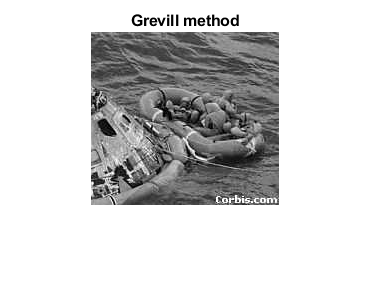

figure();
imshow(RES_Grev_uint);
title('Grevill method');

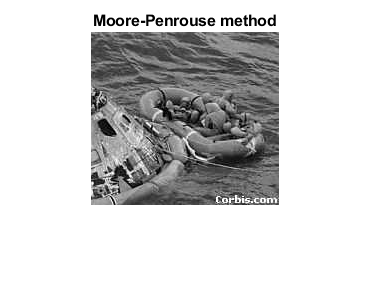

figure();
imshow(RES_MP_uint);
title('Moore-Penrouse method');